# 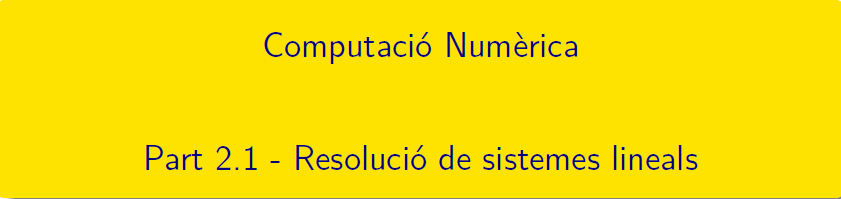

=====================================================================================

# TEMA 2 Àlgebra lineal numèrica (I)

## Part 2.0 - Vectors, Matrius i Normes

### Normes de vectors

w = [1,2,3,-4,-5,-6,0]'    % vector columna de matlab

w =      1
     2
     3
    -4
    -5
    -6
     0


abs(w)                     % componentes del vector sin signo

ans =      1
     2
     3
     4
     5
     6
     0


n1 = norm(w,1), sum(abs(w))              % norma 1    

n1 =     21


ans =     21


n2 = norm(w), sqrt(sum(w.^2))            % norma 2    

n2 =        9.5394


ans =        9.5394


ninf = norm(w,'inf')                    %norma del màxim

ninf =      6


v = [17:-1:11]           % vector fila de matlab

v =     17    16    15    14    13    12    11


v*w                                % producte escalar = (fila x columna)

ans =    -99


w.*v, w'.*v, w.*v'         % altres càlculs amb w i v

ans =     17    16    15    14    13    12    11
    34    32    30    28    26    24    22
    51    48    45    42    39    36    33
   -68   -64   -60   -56   -52   -48   -44
   -85   -80   -75   -70   -65   -60   -55
  -102   -96   -90   -84   -78   -72   -66
     0     0     0     0     0     0     0


ans =     17    32    45   -56   -65   -72     0


ans =     17
    32
    45
   -56
   -65
   -72
     0


### Normes de matrius

Moltes matrius per exemples:  ones, eye, zero, rand, randn, magic, wilkinson, hilb, invhilb, hadamard, compan, hankel, toeplitz, gallery.

A = magic(4)       % Moltes matrius per exemples 

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


sum(A), sum(A,2)  % La suma de les files i les columnes és constant

ans =     34    34    34    34


ans =     34
    34
    34
    34


norm(A,1), norm(A,'inf')

ans =     34


ans =     34


B = [1 1 0 0; -3 -2 -100 35; 0.1 0.01 2000 1/2000]

B =             1            1            0            0
           -3           -2         -100           35
          0.1         0.01         2000       0.0005


format shortG
norm(B,1), norm(B,'inf'), norm(B,2), norm(B,'fro')

ans =         2100


ans =        2000.1


ans =        2002.5


ans =        2002.8


Radi espectral (pàg 16, bloc 0)

rho = abs(eigs(A,1))

rho =            34


Nombre de condició d'una matriu (pàg 17, bloc 0)

cond(A), det(A), rcond(A)

ans =    4.7133e+17


ans =    5.1337e-13


ans =    4.6259e-18


### Tipus de matrius

A = magic(3) 

A =      8     1     6
     3     5     7
     4     9     2


tril(A), tril(A,-1), tril(A,2)

ans =      8     0     0
     3     5     0
     4     9     2


ans =      0     0     0
     3     0     0
     4     9     0


ans =      8     1     6
     3     5     7
     4     9     2


triu(A), triu(A,2), triu(A,-1)

ans =      8     1     6
     0     5     7
     0     0     2


ans =      0     0     6
     0     0     0
     0     0     0


ans =      8     1     6
     3     5     7
     0     9     2


B = (A+A')/2,  B == B'  % Simètrica

B =      8     2     5
     2     5     8
     5     8     2


ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


C = (A-A')/2, C'==-C   % Antisimètrica

C =      0    -1     1
     1     0    -1
    -1     1     0


ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


### Exercici: Tranformacions ortogonals

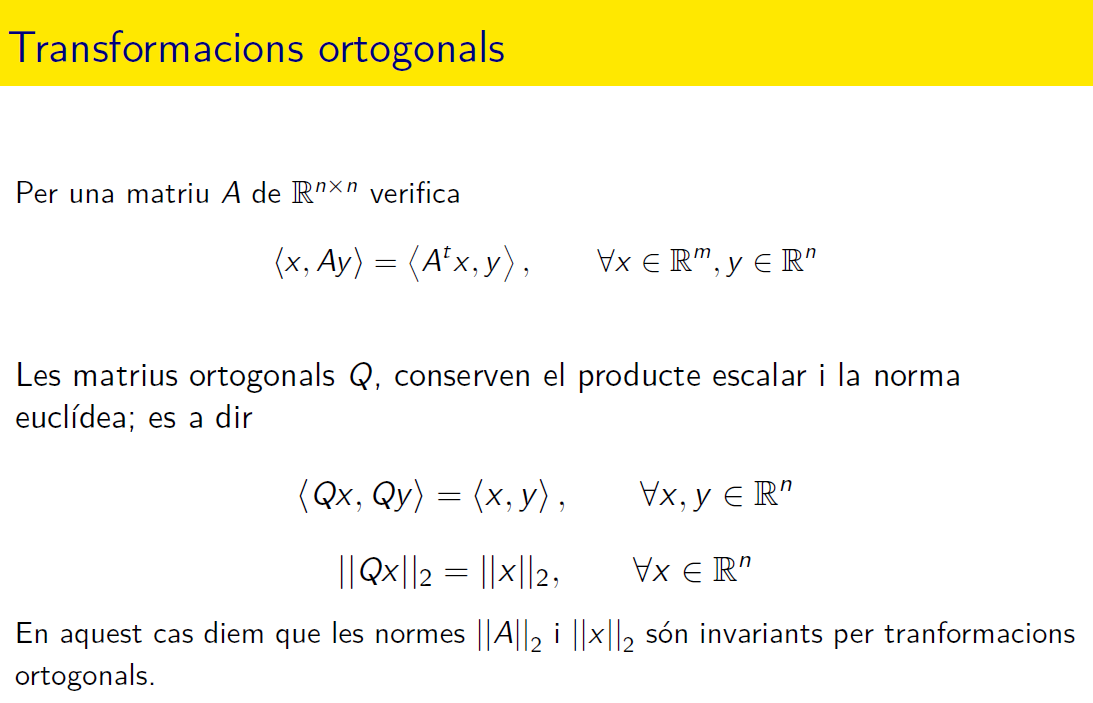

format shortG
% x'*(Ay)  =  (A'*x)'*y
A = gallery('lehmer',5)     % Una matriu de la biblioteca

A =             1          0.5      0.33333         0.25          0.2
          0.5            1      0.66667          0.5          0.4
      0.33333      0.66667            1         0.75          0.6
         0.25          0.5         0.75            1          0.8
          0.2          0.4          0.6          0.8            1


x = ones(5,1); y = diag(hilb(5));   [x,y]  % dos vectors columna

ans =             1            1
            1      0.33333
            1          0.2
            1      0.14286
            1      0.11111


[x'*(A*y), (A'*x)'*y]

ans =        4.7803       4.7803


## Part 2.1 - Resolució de sistemas d'equacions lineals

### Resolució de sistemes lineales amb Matlab

Exemple

A = [6 2 -1 -1;2 4 -1 0; -1 1 4 -1; -1 0 -1 3];
b = [0 7 -1 2]';
det(A)          % determinant

ans =           201


rank(A)         % rang

ans =      4


rank([A,b])     % rang matriu ampliada

ans =      4


sol = A\b

sol =      -0.76617
       1.9104
     -0.89055
      0.11443


vector_residu = norm(A*sol-b)

vector_residu =    1.1116e-15


### Pivotar

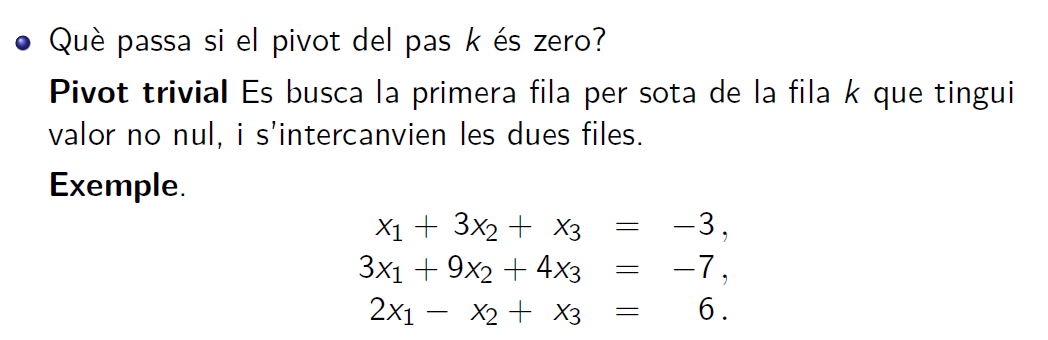

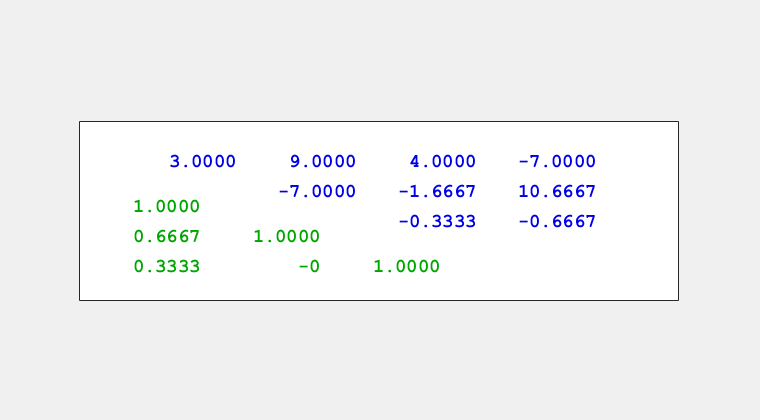

A = [1 3 1; 3 9 4; 2 -1 1];
b = [-3 -7 6]';
AM = [A,b];
[L,U,pv,qv] = lugui(AM);       % Funció de Cleve Moler, llibre Numerical Computing with Matlab

% Solució sistema
Pb = AM(pv,qv), Pb = Pb(:,end)

Pb =      3     9     4    -7
     2    -1     1     6
     1     3     1    -3


Pb =     -7
     6
    -3


% 1) Ly=Pb
y = linsolve(L,Pb)

y =            -7
       10.667
     -0.66667


% 2) Ux=y 
x = linsolve(U(:,1:end-1),y)

x =             1
           -2
            2


% verifiquem la solució
r = b - A*x, rn = norm(r)

r =             0
            0
   1.7764e-15


rn =    1.7764e-15


### Eliminació gaussiana

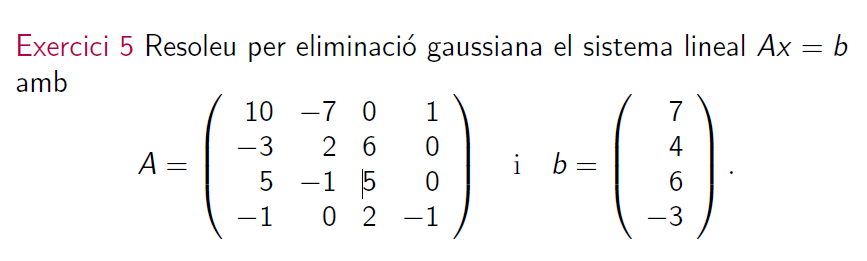

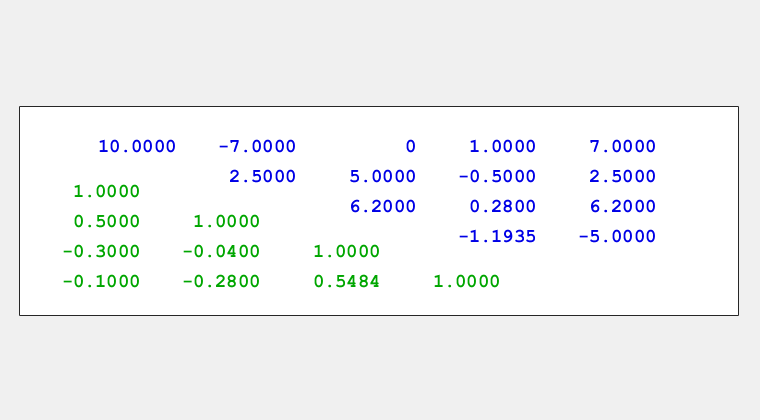

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1];
b = [7 4 6 -3]';
AM = [A,b];
% Funció de Cleve Moler, llibre Numerical Computing with Matlab
[L,U,pv,qv] = lugui(AM);        

% Solució sistema
Pb = AM(pv,qv); Pb = Pb(:,end);
% 1) Ly=Pb
y = linsolve(L,Pb)

y =     7.0000
    2.5000
    6.2000
   -5.0000


% 2) Ux=y 
x = linsolve(U(:,1:end-1),y)

x =     0.4324
    0.2162
    0.8108
    4.1892


% verifiquem la solució
r = b-A*x, rn = norm(r)

r = 	1.0e+-15 *

         0
    0.8882
   -0.8882
         0


rn = 1.2561e-15

### Factorització LU

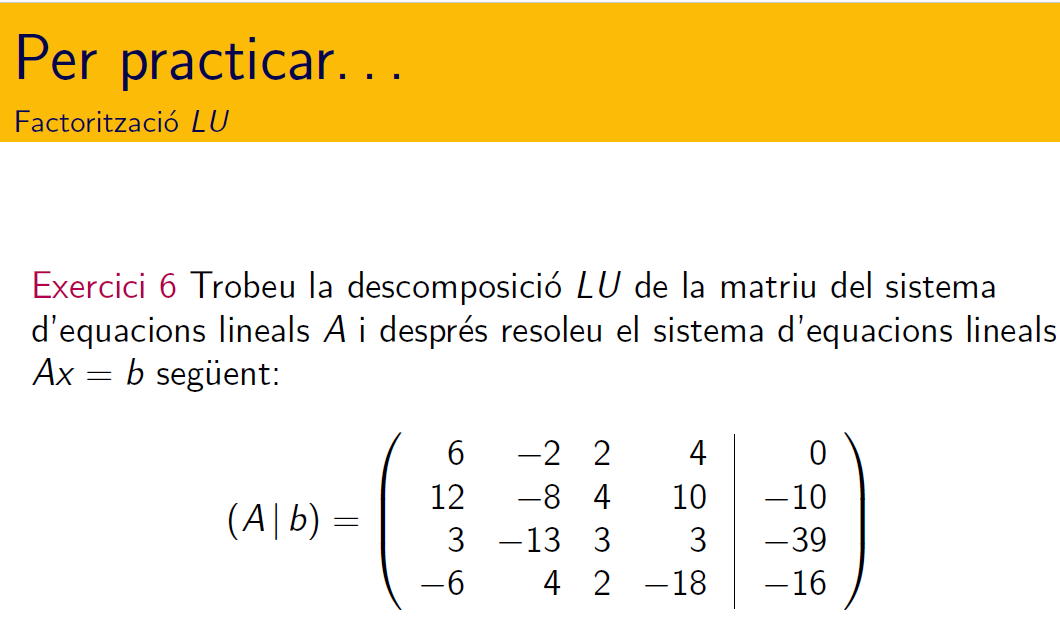

A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18 ];
b = [ 0 -10 -39 -16]';
[L,U,P] = lu(A);
% Solució sistema
% 1) Ly=Pb
y = linsolve(L,P*b);
% 2) Ux=y 
x = linsolve(U,y)

x =             1
            3
           -2
            1


% verifiquem la solució
r = b-A*x, rn = norm(r)

r =    8.8818e-16
   3.5527e-15
            0
            0


rn =    3.6621e-15


### Factorització Txoleski

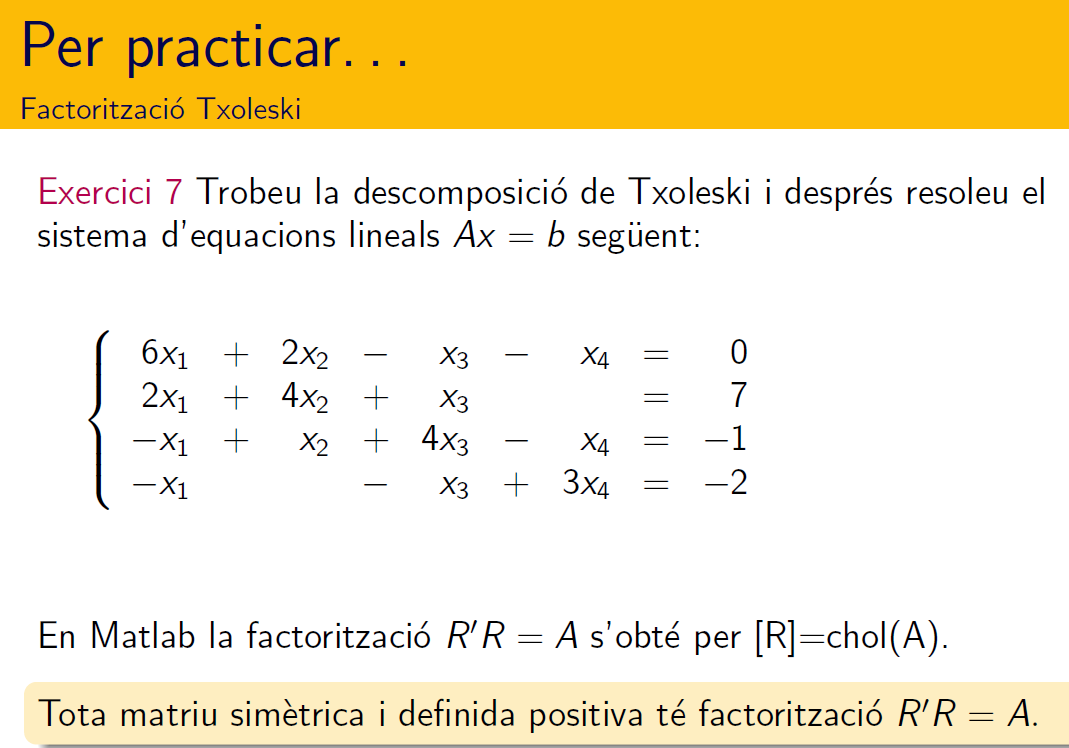

A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3];
b = [0 7 -1 -2]';
% verifiquem simetria iflag = 0
[R,iflag] = chol(A)
% comprovem R'R = A
R'*R-A
y = linsolve(R',b);
x = linsolve(R ,y)

x =       -1.6291
       3.0331
      -1.8742
      -1.8344


% verifiquem la solució
r = b-A*x, rn = norm(r)

r =    3.5527e-15
  -8.8818e-16
   6.6613e-16
            0


rn =    3.7221e-15


### Factorització QR

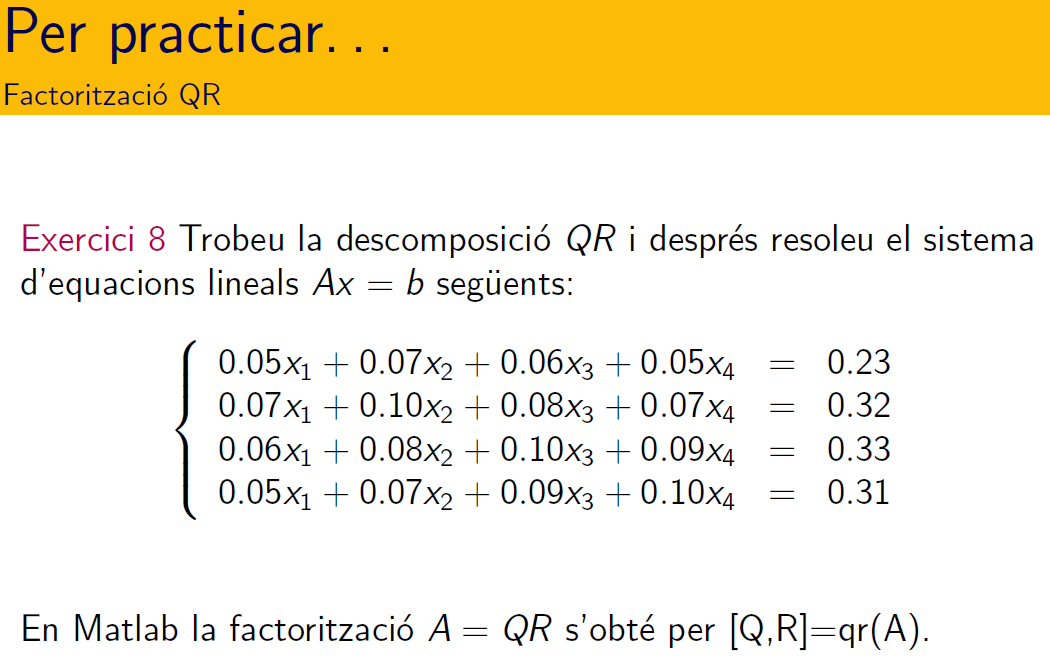        

A = [5 7 6 5; 7 10 8 7; 6 8 10 9; 5 7 9 10]/100; b = [23 32 33 31]'/100;
[Q,R] = qr(A);
% comprovem A = QR
A - Q*R

ans =    6.9389e-18            0            0   2.0817e-17
            0            0            0  -2.7756e-17
            0            0            0   1.3878e-17
            0            0            0   1.3878e-17


% la solució del sistemea és Rx=Q'b
x = linsolve(R,Q'*b)

x =             1
            1
            1
            1


% verifiquem la solució
r = b - A*x, rn = norm(r)

r =    2.7756e-17
   1.1102e-16
   5.5511e-17
   5.5511e-17


rn =    1.3878e-16


### Nombre de condició - Vector Residu

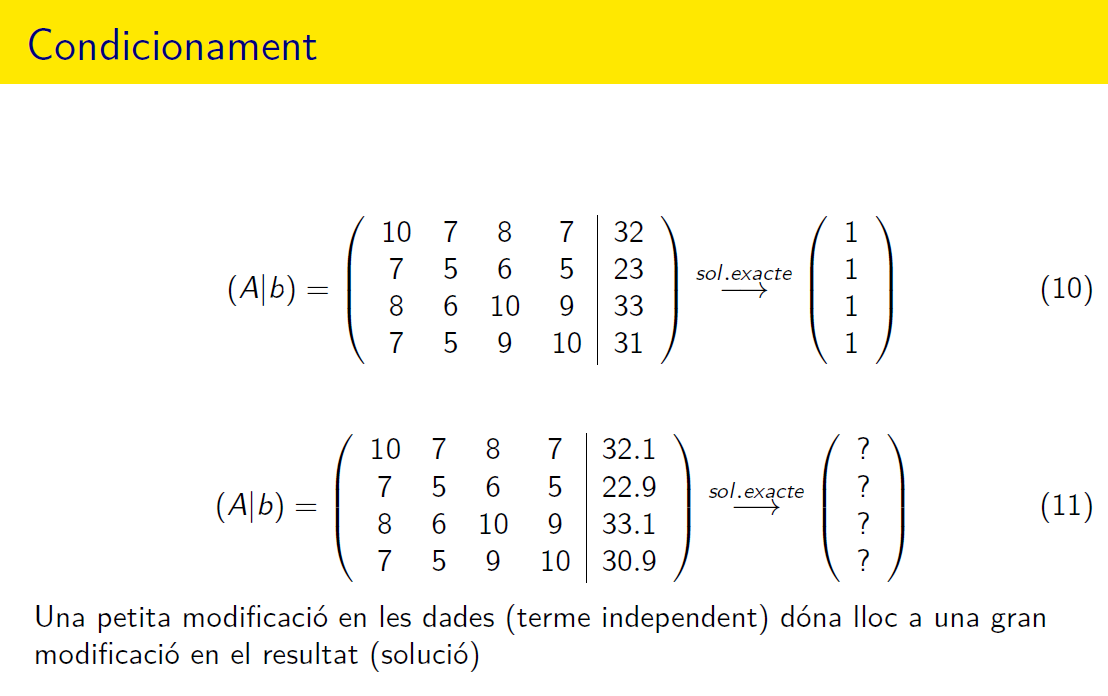

A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10];
b = [32;23;33;31];
bb = [32.1; 22.9; 33.1; 30.9];
x = A\b, y = A\bb   

x =    1.000000000000013
   0.999999999999980
   1.000000000000005
   0.999999999999997


y =    9.199999999999969
 -12.599999999999950
   4.499999999999988
  -1.099999999999993


r = norm(A*y-b,1)     

r =    0.400000000000016


db = norm(b-bb,1)

db =    0.400000000000006


format long

cond(A,1), det(A), rcond(A)

ans =      4.488000000000101e+03


ans =    0.999999999999974


ans =      2.228163992869817e-04


#### Exercici

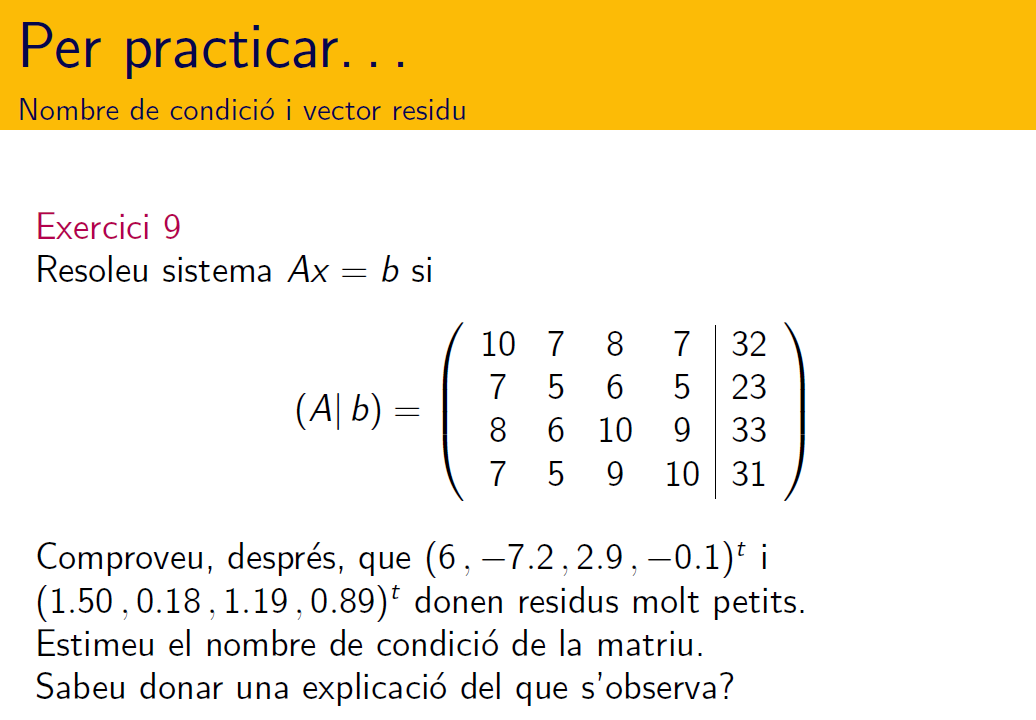

format shortG
A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]; b = [32; 23; 33; 31];
x = linsolve(A,b);
fprintf('paràmetres de condicionament\n'), K = cond(A,1), RK = rcond(A)

paràmetres de condicionament


K =          4488


RK =    0.00022282


b1 = [6, -7.2, 2.9, -0.1]';
b2 = [1.50, 0.18, 1.19, 0.89]';
B = [b1,b2],    x = A\B 

B =             6          1.5
         -7.2         0.18
          2.9         1.19
         -0.1         0.89


x =         474.8        36.68
       -785.9       -60.59
        197.2        15.22
       -116.9        -8.99


% aixo pasa perque els errors es propaguen
fprintf('vector residu\n'),rx = A*x-B

vector residu


rx =   -1.1369e-13   1.4211e-14
  -6.1373e-13  -2.8699e-14
  -1.3634e-13  -2.2204e-15
  -5.9117e-13  -2.7867e-14


prediccio = K*norm(b1-b2,1)/norm(b1,1)*100

prediccio =    4.0392e+05


valor = norm(x(:,1)-x(:,2),1)/norm(x(:,1),1)*100

valor =        92.286
